# Predator-Prey Model (LOTKA – VOLTERRA)

This livescript is a brief manual in support of the app ***Predator_prey_model.mlapp***. This is a simple interface to demonstrate behaviour of predator-prey interactions using the Lotka-Volterra model. The population of prey and predator is subject to changes in prey intrinsic growth rate, attack rate by predator, hunter condition and predator reproduction rate. Initial population of prey and predator can also be adjusted within a reasonable range.

### Similar files and the toolbox

See website below for more files like this.     

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by Z.Song with some support from J.A.Rossiter, University of Sheffield                         

## Table of contents

- Predator-Prey Interactions

- Lotka-Volterra Model

- Assumptions and Limitations

- Interface and user interaction

## 1. Predator-Prey Interactions

Predator-prey interactions are fundamental components of ecological systems, shaping the dynamics and structure of ecosystems. In these interactions, predators consume prey as a food source, exerting selective pressure on prey populations. Meanwhile, prey species have evolved various defense mechanisms to avoid predation, leading to a dynamic interplay between predator and prey populations.

Think of wolves chasing deer/rabbits in forests, fish hunting plankton in oceans, or hawks swooping down on mice in fields. These are all examples of predator-prey interactions happening all around us.

Understanding how predators and prey interact helps us understand how ecosystems work and how they respond to changes. In this LiveScript, we'll explore the Lotka-Volterra equations, a cool mathematical tool that helps us model and understand these interactions. Then, we'll use MATLAB to bring the equations to life with simulations.

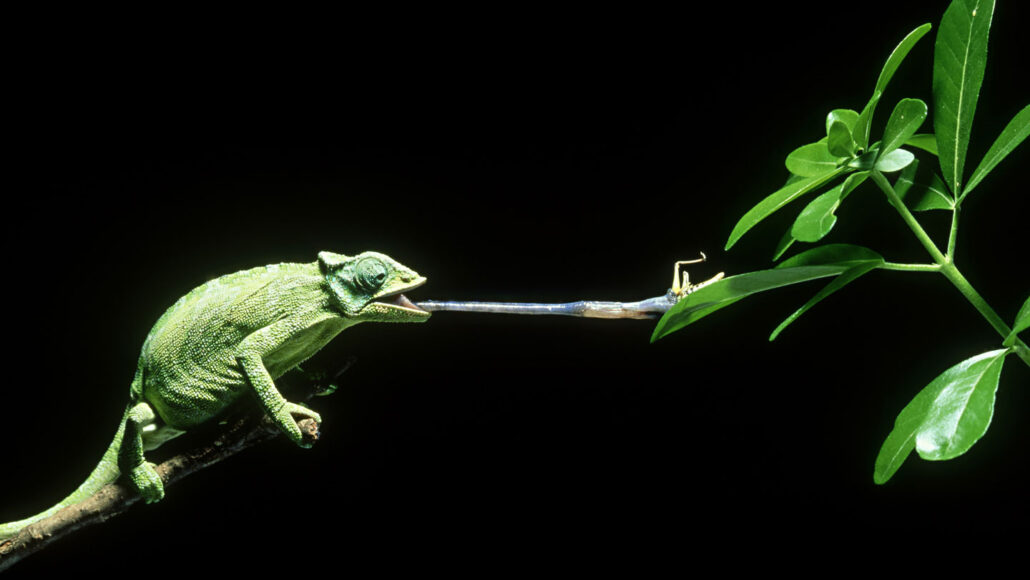

Reference to this picture can be found [here](https://www.snexplores.org/article/scientists-say-predator-and-prey-definition-pronunciation#:~:text=The%20words%20%E2%80%9Cpredator%E2%80%9D%20and%20%E2%80%9C,the%20one%20that%20gets%20eaten.). 

## 2. Lotka-Volterra Model

We wish to see how prey population $X$ and predator population $Y$ will change over time $t$, given their initial population $X_0$ and $Y_0$ and other environmental parameters. A pair of first-order nonlinear differential equations can thus be used to model this interaction behaviour, known as Lotka-Volterra equations or predator-prey equations. 

For the prey population $X$:


$$\frac{\textrm{dX}}{\textrm{dt}}=\textrm{rX}-\alpha \textrm{XY}$$


For the predator population $Y$:


$$\frac{\textrm{dY}}{\textrm{dt}}=-\textrm{mY}+\beta \textrm{XY}-\textrm{hY}$$


The environmental parameters above and their usual ranges can be summarised as:

$r:$ Intrinsic growth rate of prey population, or prey's ability to reproduce in the absence of predators (0.1-1).

$\alpha :$ Rate at which the prey is captured and consumed by predators (0.01-0.1).

$\beta :$ Rate at which predators increase by consuming prey (0.01-0.1).

$m:$ Mortality rate of predators (0.1-1).

$h:$ Rate at which predators decrease in the absence of prey (0.01-0.1).

Let's try out these equations in an example. Suppose there are wolves as predators and rabbits as prey. To start with, there are 40 rabbits and 9 wolves. Given that rabbits' intrinsic growth rate $r$ is 0.8, attack rate by wolves $\alpha$ is 0.03, wolves' reproduction rate $\beta$ is 0.01, wolves' mortality rate $m$ is 0.3, and wolves' loss rate in the absence of rabbits $h$ is 0.3.

Then, the progression of rabbits' population $X$ and wolves' population $Y$ with respect to time $t$ can be plotted below. 

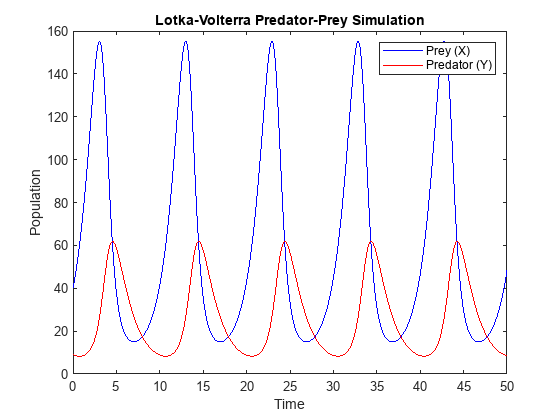

% Example of predator-prey model
r = 0.8;  % Prey intrinsic growth rate (0.1-1) 
a = 0.03; % Predator attack rate (0.01-0.1)
b = 0.01;  % Predator reproduction rate (0.01-0.1) --> to control prey > predator
m = 0.3;  % Predator mortality rate (0.1-1)
h = 0.3; % Predator loss rate in the absence of prey (0.1-1)

% Initial conditions (prey and predator populations at time t=0)
X0 = 40;  % Initial prey population 40
Y0 = 9;   % Initial predator population 9

% Time span for the simulation (e.g., from 0 to 50 time units)
tspan = [0 50];

% Define the ODE solver options (optional but can be helpful)
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-6);

% Set up the function handle for the Lotka-Volterra equations
lotka_volterra_fun = @(t, x) lotka_volterra(t, x, r, a, b, m, h);

% Simulate the system
[t, populations] = ode45(lotka_volterra_fun, tspan, [X0; Y0], options);

% Extract prey and predator populations at each time point
X = populations(:, 1);
Y = populations(:, 2);

% Plot the results
figure;
plot(t, X, 'b', t, Y, 'r');
xlabel('Time');
ylabel('Population');
legend('Prey (X)', 'Predator (Y)');
title('Lotka-Volterra Predator-Prey Simulation');

We can even generate a phase plot based on this progression, as shown below.

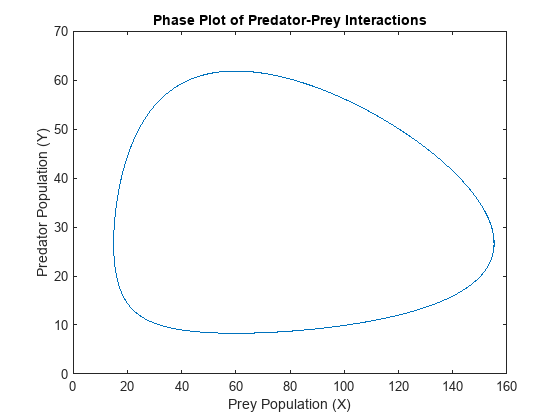

% Phase plot
figure;
plot(X,Y);
xlabel('Prey Population (X)');
ylabel('Predator Population (Y)');
title('Phase Plot of Predator-Prey Interactions');

function dxdt = lotka_volterra(t, x, r, a, b, m, h)
    % Lotka-Volterra equations
    dxdt(1,1) = r * x(1) - a * x(1) * x(2);
    dxdt(2,1) = -m * x(2) + b * x(1) * x(2) - h * x(2);
end

Now it's your turn! Explore the simulations with different parameter values. This can provide insights into how ecological systems respond to various conditions.

## 3. Assumptions and Limitations

As you play with the paramaters and draw the plots, you may find out that there are counter-intuitive things. 

Well, you are not wrong. 

One of the most significant problems of the Lotka-Volterra equations as a biological model is the ability of a prey population to "bounce back" even when subjected to extremely low population numbers. In other words, extinction does not appear in this model, which makes some scenarios not that natural. You may also find out that, with some specific parameter values chosen, predator population can potentially reach larger numbers than prey population. 

These unrealistic feelings actually stem from the Lotka-Volterra model's assumptions, which are listed below. 

Assumption 1: The prey population finds ample food at all times.

Assumption 2: The food supply of the predator population depends entirely on the size of the prey population.

Assumption 3: The rate of change of population is proportional to its size.

Assumption 4: During the process, the environment does not change in favour of one species, and genetic adaptation is inconsequential.

Assumption 5. Predators have limitless appetite.

These simplifications, such as constant parameters, no immigration or emigration, and a homogeneous environment, may not capture the complexity of real ecosystems. Certain parameter combinations may lead to unrealistic outcomes. 

Thus, it's important to note that the Lotka-Volterra model has limitations, and its predictions should be interpreted with caution. In real ecosystems, various factors, such as spatial heterogeneity, multiple prey species, and additional ecological interactions, contribute to more complex dynamics. In many cases, predator-prey interactions are regulated by a combination of factors, including food availability, environmental conditions, and the presence of other species.

In summary, the counterintuitive result of predators reaching larger numbers than prey in the Lotka-Volterra model often arises from specific parameter values and assumptions. Real ecosystems are more complex, and the model should be considered a basic framework rather than a definitive representation of all predator-prey interactions.

More information can be found in these slides by USC: 

[https://sail.usc.edu/~lgoldste/ArtPhon/Slides/lotka-volterramodel.pdf](https://sail.usc.edu/~lgoldste/ArtPhon/Slides/lotka-volterramodel.pdf)

## 4. Interface and user interaction

The animation shows two circles, representing prey and predator population respectively, changing their sizes according to prey-predator interactions.

- If a hunter is introduced for either prey or predator, this appears in the figure as "Hunter!" on top of the corresponding population circle. When there is no hunter considered, the text disappears.

- The prey growth rate and attack rate by predators are shown respectively on the left and right side, like bar plots. Qualitive rate levels are shown below each bar.

- The animation runs for about 10-15 seconds to show the responses in the current scenario; this includes animation of the line plots.

The user can change only a few parameters as we want to keep the app simple and transparent to use.

- Initial population of prey and predator

- Intrinsic growth rate of prey

- Attack rate by predator

- Hunter condition. If there are hunters introduced, their target can be either the prey or predator species.

Please note that, once the "Simulate" button is clicked, no more changes will be taken as inputs before the current round of simulation finishes. 

Users cannot stabilize population of one species using control techniques such as PID, as we did not want to overload the interface. Delay in responses is also expected when introducing new conditions (such as hunters) as a control method. Users are encouraged to explore suitable ways to stablize either prey or predator population level.

Users can run the simulation with various choices of parameters and overlay the results so they can build a picture and understanding of the impact of different changes. To refresh and begin again, use the "Refresh" button.